% Homework 1. Due before class on 9/5/17
disp('Siqi Du sd72')

## Problem 1 - addition with strings

% Fill in the blank space in this section with code that will add 
% the two numbers regardless of variable type. Hint see the matlab
% functions ischar, isnumeric, and str2num. 

% your code should work no matter which of these lines is uncommented. 
% x = 3; y = 5; % integers
% x = '3'; y= '5'; %strings
x = 3; y = '5'; %mixed

% your code goes here
if ischar(x) == 1
    x = str2num(x);
end
if ischar(y) == 1
    y = str2num(y);
end

% output your answer
disp(x+y)

## Problem 2 - our first real biology problem. Open reading frames and nested loops.

% part 1: write a piece of code that creates a random DNA sequence of length
% N (i.e. consisting of the letters ATGC) where we will start with N=500 base pairs (b.p.).
% store the output in a variable
% called rand_seq. Hint: the function randi may be useful. 
% Even if you have access to the bioinformatics toolbox, 
% do not use the builtin function randseq for this part. 
clear all
rand_seq = zeros(1,500);
N = 500; % define sequence length
rand_num = randi(4,1,N);
for ii = 1:N
    switch rand_num(ii)
        case 1
            rand_seq(ii) = 'A';
        case 2
            rand_seq(ii) = 'T';
        case 3
            rand_seq(ii) = 'G';
        case 4
            rand_seq(ii) = 'C';
    end
end
char(rand_seq)
% SeqLength = 500;
% bases = repmat('ACGT', 1, SeqLength/4);
% rand_seq = bases(randperm(SeqLength));

% part 2: open reading frames (ORFs) are pieces of DNA that can be
% transcribed and translated. They start with a start codon (ATG) and end with a
% stop codon (TAA, TGA, or TAG). Write a piece of code that finds the longest ORF 
% in your seqeunce rand_seq. Hint: see the function strfind.
% strfind is to show postion of a specific string.

% [m,i] = max(A), i can also show the position
% find(max(A)==A) can show the position

% Find start and cloest stop codon positions
start = sort(strfind(rand_seq, 'ATG'));
for jj = 1:numel(start)
    ORF1 = rand_seq(start(jj):N);
    stop1 = strfind(ORF1, 'TAA');
    stop2 = strfind(ORF1, 'TGA');
    stop3 = strfind(ORF1, 'TAG');
    stop = [stop1 stop2 stop3];
    lengthover0 = stop > 0;
    lengthmultiple3 = rem(stop, 3) == 0;
    candidate = stop(lengthmultiple3 & lengthover0);
    if isempty(candidate)
        maximum(jj) = 0;
    else
        maximum_temp = min(candidate);
        maximum(jj) = maximum_temp;
    end
end
[length, iii] = max(maximum);
% Get the longest ORF start and stop positions and output them, and check
% if they are multiple of 3
% Display the longest ORF
LongORF = rand_seq(start(iii):start(iii)+max(maximum));
char(LongORF)
% Easier way to do it but don't check if it's multiple of 3
% start = strfind(rand_seq, 'ATG');
% stop1 = strfind(rand_seq, 'TAA');
% stop2 = strfind(rand_seq, 'TGA');
% stop3 = strfind(rand_seq, 'TAG');
% stop = [stop1 stop2 stop3];
% start_position = min(start);
% stop_position = max(stop);
% LongORF = rand_seq(1,start_position:stop_position);
% char(LongORF)

%part 3: copy your code in parts 1 and 2 but place it inside a loop that
% runs 1000 times. Use this to determine the probability
% that an sequence of length 500 has an ORF of greater than 50 b.p.

% Generate 1000 sequences of 500 bp from rand_seq
N = 500;
rand_seq = zeros(1,N);
pp = 0;
for qq = 1:1000
    rand_num = randi(4,1,N);
    for ii = 1:N
        switch rand_num(ii)
            case 1
                rand_seq(ii) = 'A';
            case 2
                rand_seq(ii) = 'T';
            case 3
                rand_seq(ii) = 'G';
            case 4
                rand_seq(ii) = 'C';
        end
    end
    start = sort(strfind(rand_seq, 'ATG'));
    for jj = 1:numel(start)
        ORF1 = rand_seq(start(jj):N);
        stop1 = strfind(ORF1, 'TAA');
        stop2 = strfind(ORF1, 'TGA');
        stop3 = strfind(ORF1, 'TAG');
        stop = [stop1 stop2 stop3];
        lengthover0 = stop > 0;
        lengthmultiple3 = rem(stop, 3) == 0;
        candidate = stop(lengthmultiple3 & lengthover0);
        if isempty(candidate)
            maximum(jj) = 0;
        else
            maximum_temp = min(candidate);
            maximum(jj) = maximum_temp;
        end
    end
    [length, iii] = max(maximum);
    if length > 50
       pp = pp + 1;
    end
end
prob = pp/1000

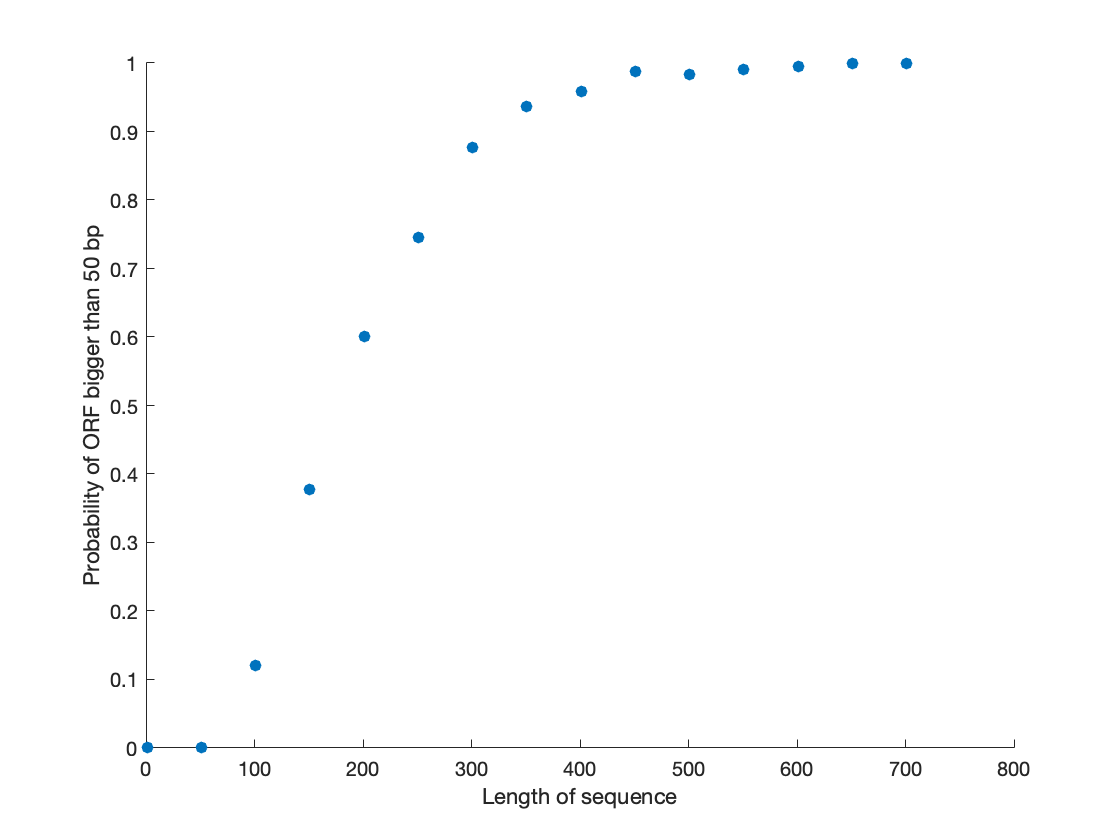

% part 4: copy your code from part 3 but put it inside yet another loop,
% this time over the sequence length N. Plot the probability of having an
% ORF > 50 b.p. as a funciton of the sequence length. 
% dbstep for debug step by step
clear
nn = 1;
for N = 1:50:701
    pp = 0;
    for qq = 1:1000
    rand_num = randi(4,1,N);
        for ii = 1:N
            switch rand_num(ii)
                case 1
                    rand_seq(ii) = 'A';
                case 2
                    rand_seq(ii) = 'T';
                case 3
                    rand_seq(ii) = 'G';
                case 4
                    rand_seq(ii) = 'C';
            end
        end
        start = sort(strfind(rand_seq, 'ATG'));
        if ~isempty(start)
            for jj = 1:numel(start)
                ORF1 = rand_seq(start(jj):N);
                stop1 = strfind(ORF1, 'TAA');
                stop2 = strfind(ORF1, 'TGA');
                stop3 = strfind(ORF1, 'TAG');
                stop = [stop1 stop2 stop3];
                lengthover0 = stop > 0;
                lengthmultiple3 = rem(stop, 3) == 0;
                candidate = stop(lengthmultiple3 & lengthover0);
                if isempty(candidate)
                    maximum(jj) = 0;
                else
                    maximum_temp = min(candidate);
                    maximum(jj) = maximum_temp;
                end
            end
            [length, iii] = max(maximum);
            if length > 50
               pp = pp + 1;
            end
        end
    end
        prob(nn) = pp/1000;
        nn = nn + 1;
end
N = 1:50:701;
figure(1);
scatter(N,prob,'filled')
xlabel('Length of sequence')
ylabel('Probability of ORF bigger than 50 bp')

%part 5: Make sure your results from part 4 are sensible. What features
% must this curve have (hint: what should be the value when N is small or when
% N is very large? how should the curve change in between?) Make sure your
% plot looks like this.

## problem 3 data input/output and simple analysis

%The file qPCRdata.txt is an actual file that comes from a Roche
%LightCycler qPCR machine. The important columns are the Cp which tells
%you the cycle of amplification and the position which tells you the well
%from the 96 well plate. Each column of the plate has a different gene and
%each row has a different condition. Each gene in done in triplicates so
%columns 1-3 are the same gene, columns 4-6 the same, etc.
%so A1-A3 are gene 1 condition 1, B1-B3 gene 1 condition 2, A4-A6 gene 2
%condition 1, B4-B6 gene2 condition 2 etc. 

% part1: write code to read the Cp data from this file into a vector. You can ignore the last two
% rows with positions beginning with G and H as there were no samples here. 

% qPCR = fopen("qPCRdata.txt", 'r');
% line1 = fgetl(qPCR);
% q=1;
% var1 = strsplit(line1, 't\')

% qPCR_table = readtable("qPCRdata.txt");
% qPCR_array = table2array(qPCR_table(:,5));

qPCR = importdata("qPCRdata.txt");
qPCR_Cp = qPCR.data(1:72,1);

% Part 2: transform this vector into an array representing the layout of
% the plate. e.g. a 6 row, 12 column array should that data(1,1) = Cp from
% A1, data(1,2) = Cp from A2, data(2,1) = Cp from B1 etc. 

% qPCR_Cp2 = reshape(qPCR_Cp,6,12)?
for ii = 1:6
    qPCR_Cp_Organized(ii,:) = qPCR_Cp(ii*12-11:ii*12,1);
end

% Part 3. The 4th gene in columns 10 - 12 is known as a normalization gene.
% That is, it's should not change between conditions and it is used to normalize 
% the expression values for the others. For the other three
% genes, compute their normalized expression in all  conditions, normalized to condition 1. 
% In other words, the fold change between these conditions and condition 1. The
% formula for this is 2^[Cp0 - CpX - (CpN0 - CpNX)] where Cp0 is the Cp for
% the gene in the 1st condition, CpX is the value of Cp in condition X and
% CpN0 and CpNX are the same quantitites for the normalization gene.
% Plot this data in an appropriate way.

% Get mean value for control group
for ii = 1:6
    CpNr(ii) = mean(qPCR_Cp_Organized(ii,10:12));
end
CpNc = CpNr';
% Get mean value for experimental groups
for qq = 1:6
    for pp = 1:3
        Cpr(pp,qq) = mean(qPCR_Cp_Organized(qq,1*pp:3*pp));
    end
end
Cpc = Cpr';
% Get the fold change
for ii = 2:6
    for jj = 1:3
        result(ii-1,jj) = 2^[Cpc(1,jj) - Cpc(ii,jj) - (CpNc(1,1) - CpNc(ii,1))];
    end
end
bar(result)
title('qPCR results')
xlabel('condition')
ylabel('fold change')
set(gca,'xtickLabel',{'cond2','cond3','cond4','cond5','cond6'})
legend('gene1','gene2','gene3')

## Challenge problems that extend the above (optional)

% 1. Write a solution to Problem 2 part 2 that doesn't use any loops at
% all. Hint: start by using the built in function bsxfun to make a matrix of all distances
% between start and stop codons. 

% start = strfind(rand_seq, 'ATG');
% stop1 = strfind(rand_seq, 'TAA');
% stop2 = strfind(rand_seq, 'TGA');
% stop3 = strfind(rand_seq, 'TAG');
% stop = [stop1 stop2 stop3]';
% ORF = bsxfun(@minus, 

% 2. Problem 2, part 4. Use Matlab to compute the exact solution to this
% problem and compare your answer to what you got previously by testing
% many sequences. Plot both on the same set of axes. Hint: to get started 
% think about the following:
% A. How many sequences of length N are there?
% B. How many ways of making an ORF of length N_ORF are there?
% C. For each N_ORF how many ways of position this reading frame in a
% sequence of length N are there?

% 3. Problem 3. Assume that the error in each Cp is the standard deviation
% of the three measurements. Add a section to your code that propogates this
% uncertainty to the final results. Add error bars to your plot. (on
% propagation of error, see, for example:
% https://en.wikipedia.org/wiki/Propagation_of_uncertainty